# Lab 1: Sampled-Data Systems are Different

Pranshu Malik (`1004138916`) and Varun Sampat (`1003859602`)

In this lab we explore how the discretization of the plant can affect the control performance. An inherently Continuous-time (CT) linear time-invariant (LTI) system or plant is first discretized to find its Discrete-time (DT) equivalent where we analyze the impact of aliasing. Then we investigate the stability of the closed loop DT system with a simple gain controller, and lastly we analyze the inter-sample differences between a fully DT closed-loop system and CT closed-loop system with a DT controller.

## 1. Aliasing

We consider the CT LTI plant with transfer function $G(s) = \frac{1}{s^2 + 0.8s + 1}$. The frequency response of this plant is given below.

Gs = tf(1, [1 0.8 1]);   % plant transfer function
bodeplot(Gs, {0, 2*pi}); % bode plot of G(s)
grid on;

The Bode plot above can be regarded as the continuous-time Fourier transform (CTFT) of the plant's impulse response $g(t)$. Now, we sample$g(t)$ every $T_s$ seconds to obtain a sequence $g[k] = g(kT_s)$. The discrete-time Fourier transform (DTFT) of this sequence is $G(e^{j\omega}) = \frac{1}{T_s}\sum_k G\left( j \left(\frac{\omega}{T_s}-\frac{2\pi k}{T_s}\right)\right)$ where $G(j\Omega)$ is the CTFT of $g(t)$, $\omega \text{ [rad]} = \Omega \text{ [rad/s] } T_s$ is the normalized angular frequency, and $-\infty<k<\infty$. But it is easy to observe that $G(e^{j\omega})$is periodic with period $2\pi$. Furthermore, we can express the same in a generalized-DTFT form in the $z$-domain where $z\in\mathbb{C}$. The corresponding $Z$-transform of $g[k]$is given by $G(z) = Z\Big[\mathcal{S}\big(\mathcal{L}^{-1}[G(s)]\big)\Big]$where $\mathcal{S}$ is the sampling operation.

% sample the CT impulse response of the plant to get its DTFT
Ts = 1;
Gz = c2d(Gs, Ts, 'impulse') % discretized impulse response, g(t) <-> G(z)

Gz =
 
   0.5803 z - 2.278e-17
  -----------------------
  z^2 - 0.8159 z + 0.4493
 
Sample time: 1 seconds
Discrete-time transfer function.



% frequency response plots of G(z)
figure;
freqz(Gz.Numerator{:}, Gz.Denominator{:}, 512, 'whole', 1/Ts);
grid on;

Since the CTFT contained energy across the entire spectrum, i.e., it was not bandlimited in the ideal sense, we will have aliasing in the sampled sequence where energy outside the bandwidth of the Nyquist frequency $\frac{\Omega_s}{2} = \Omega_N$ (which is $0.5 \text{ Hz}$ in our case) will "pack" into the sampled-signal band, which can be seen above. We also confirm the same below by plotting over $\omega \in [0,\pi] \text{ rad}$.

% since Ts = 1, we can use bodeplot(.) to overlay G(s) and G(z)
figure;
bp = bodeplot(Gs, Gz, {0, pi}); % bode plot of G(z) and G(s)
setoptions(bp,'FreqScale','linear','FreqUnits','Hz','Grid','on');
set(legend('$G(s)$', '$G(z)$'), 'Interpreter', 'latex');

In the magnitude response, due to superimposition of repeated copies of CTFT, we can see a clear divergence from the original CTFT above. But since the sampling frequency lies about an order of magnitude away from the peak of magntitude response of the low-pass system, even despite aliasing, the frequency characteristics of the sampled response match closely with the continuous response for the most part.

Now, we obtain the DT model of the CT system by discretizing the transfer function which involves a cascade of a zero-order hold block, the CT plant, and the sampler block. The net system can then be thought to operate entirely in discrete-time and the corresponding DT transfer function of the plant is given by $G_d(z) = \frac{z-1}{z}Z\bigg[\mathcal{S}\Big(\mathcal{L}^{-1}\Big[\frac{G(s)}{s}\Big]\Big)\bigg]$.

% discretized transfer function in state-space representation
sysc     = ss(Gs);
[Ad, Bd] = c2d(sysc.A, sysc.B, Ts)

Ad =     0.1758   -0.5803
    0.5803    0.6401


Bd =     0.5803
    0.3599


% discretized transfer function of the plant, Gd(z)
sysd = ss(Ad, Bd, sysc.C, sysc.D, Ts);
Gd   = tf(sysd)

Gd =
 
     0.3599 z + 0.2735
  -----------------------
  z^2 - 0.8159 z + 0.4493
 
Sample time: 1 seconds
Discrete-time transfer function.



% bode plots of G(s), G(z), and Gd(z)
% again using bodeplot(.) option since Ts = 1; can use freqz if Ts != 1
figure;
dp = bodeplot(Gs, Gz, Gd, {0, pi});
setoptions(dp,'FreqScale','linear','FreqUnits','Hz','Grid','on');
set(legend('$G(s)$', '$G(z)$', '$Gd(z)$'), 'Interpreter', 'latex');

We have already noted above that the sampled impulse response is aliased and therefore $G(z)$ diverges from $G(s)$. However, the discretized system response $G_d(z)$ is capturing the entire input and output transformations of the plant to make it compatible with DT controllers. Hence, it is different from the true CT response of the plant, but it is also different from the sampled response due to the additional the incorporation of the zero-order hold block (other than the sampler block). Notably, $G_d(z)$ has higher phase offset which again shows the incorporation of the hold operation that a naturally introduces a delay in the system, known as the transport delay. But overall, from the plots above, both approximations are close when far from the Nyquist limit of $0.5 \text{ Hz}$. But note that $G_d(z)$, by construction, will result in the exact state evolution as $G(s)$ over timesteps of $T_s$, and so it is the accurate DT representation of the CT plant $G(s)$, whereas $G(z)$is not. We will investigate this further in section 3.

## 2. Effects of Sample and Hold on Control Design

This section explores how system stability is affected by discretization.

**2.1 Estimating Zero-Order Hold Time Delay as Transport Delay**

The hold operator introduces a time delay effect on the input signal. If the sampling time is $T$ , the hold operator can be approximated, at low frequency, by a time delay of $\frac{T}{2}$. This approximation was invetigated through the following Simulink setup:

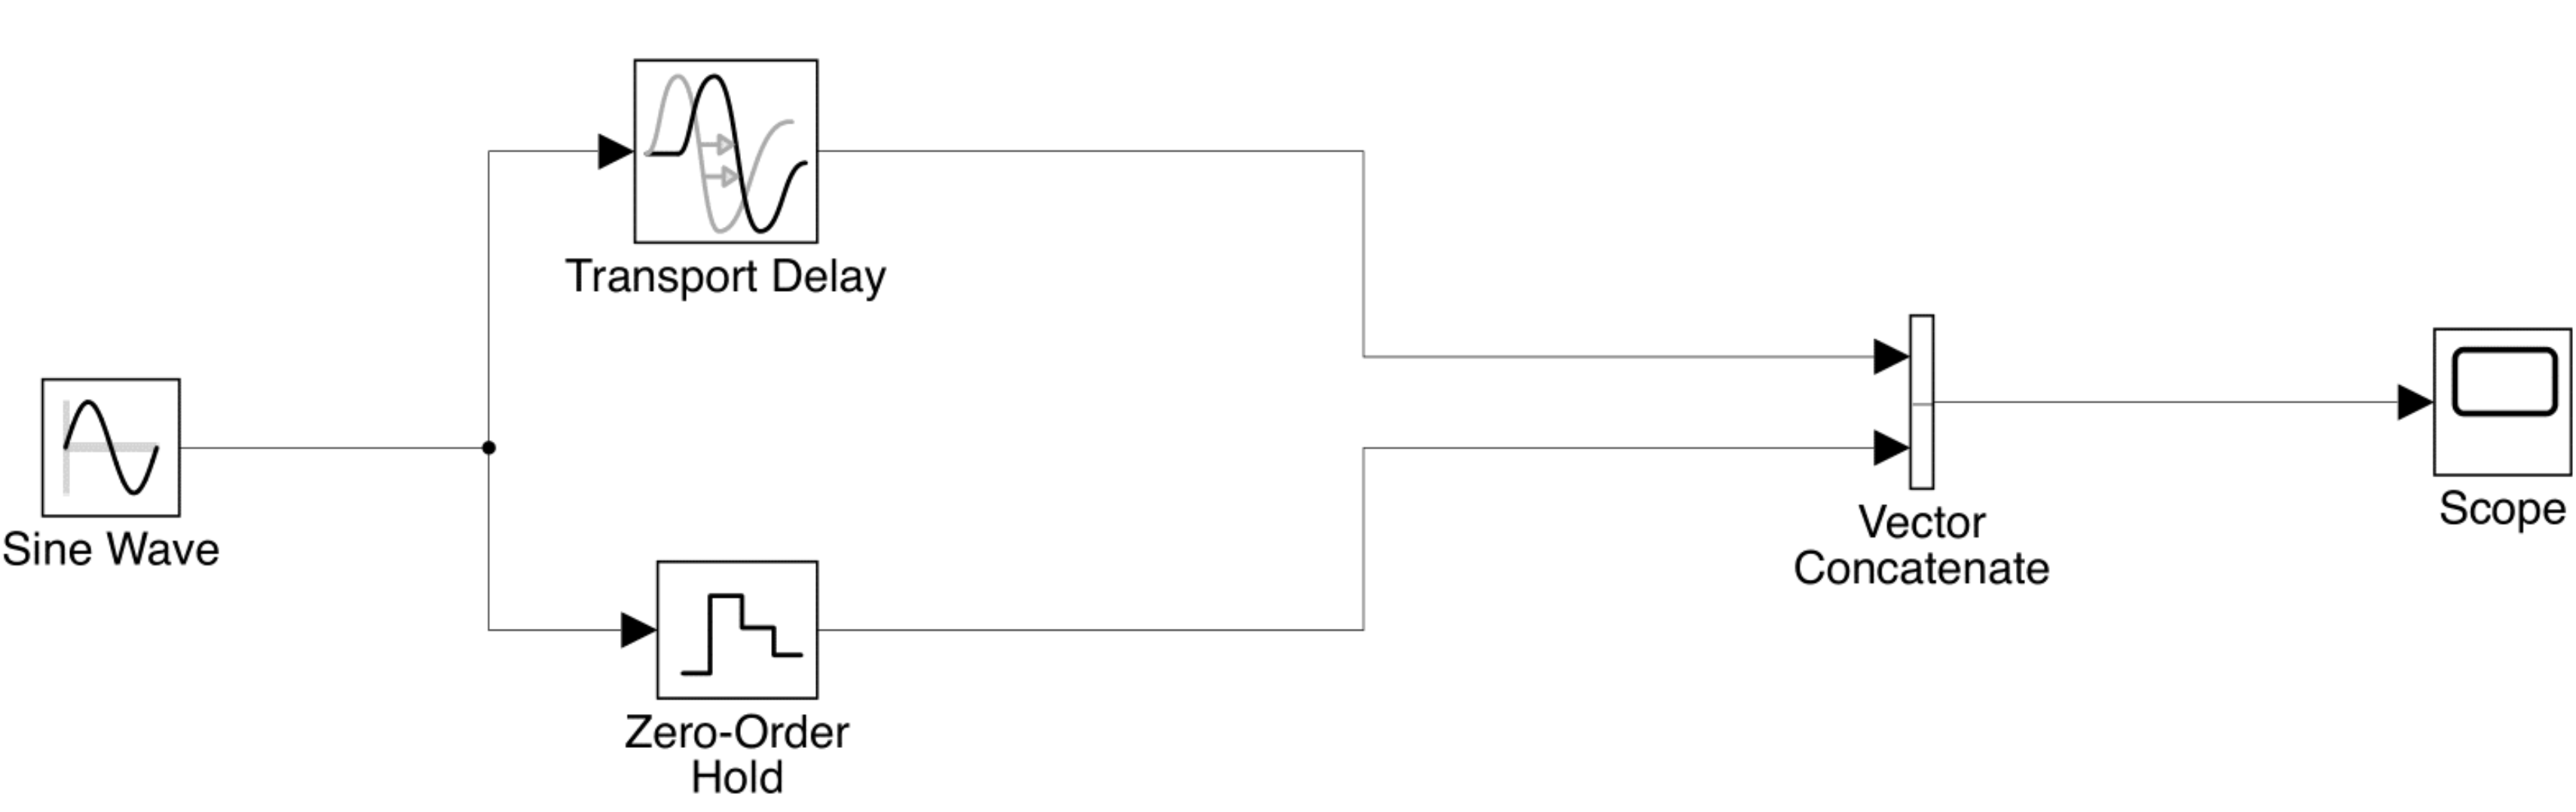

The frequency of the sine wave was varied to explore when the approximation of a transport delay as a zero-order hold stands. 


$$r\left(t\right)=\sin \left(\frac{1}{3}t\right)$$


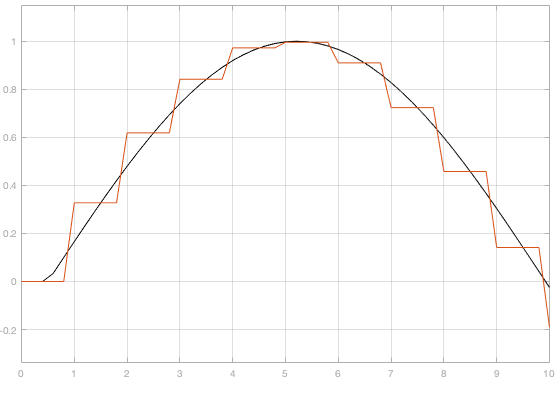


$$r\left(t\right)=\sin \left(\frac{1}{2}t\right)$$


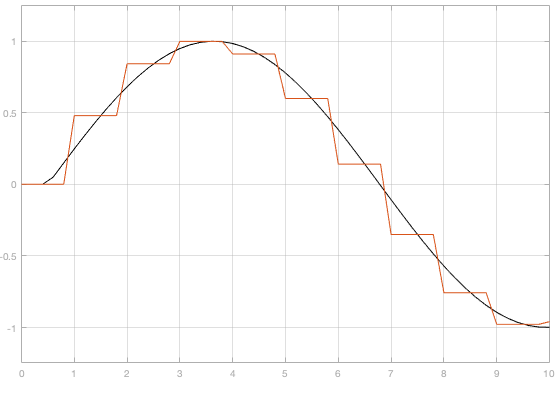


$$r\left(t\right)=\sin \left(t\right)$$


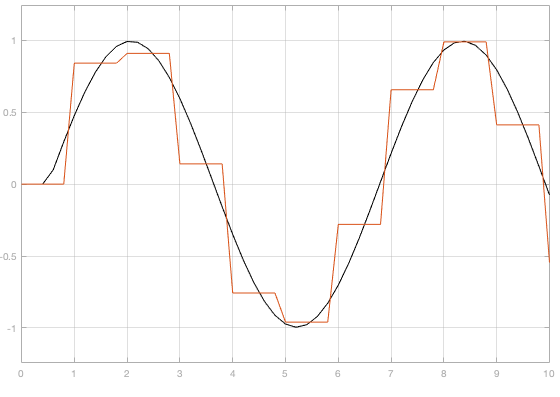


$$r\left(t\right)=\sin \left(2t\right)$$


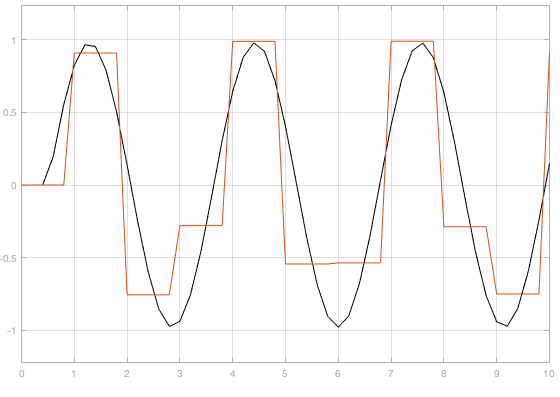


$$r\left(t\right)=\sin \left(4t\right)$$


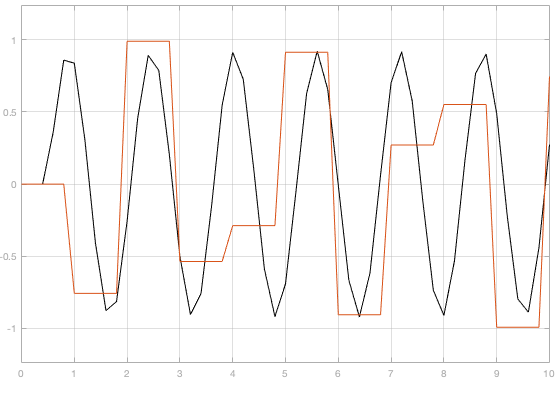

*Observations:*

- The transport delay block delays the input by $\frac{T_s }{2}$sec, which is 0.5s in this simulation. It is easy to recognize that the black line in all of the graphs above corresponds to the output of the transport delay block, as all are sine waves shifted 0.5s to the right. 

- The zero-order hold block records an input value every $T_s =1$seconds. For an interval of $T_s$, any changes in the input are not recorded. The red lines in the graphs above clearly correspond to this behaviour.

- These graphs indicate that Transport Delay a good approximator of Zero-Order Hold at lower frequencies, as for lower frequencies the zero-order hold seems to follow the transport delay output. This can be justified by Nyquist's sampling theorem, which states that a signal must be samples at more than twice the highest frequency component of the input signal. Here, regardless of changing the $f$of the signal, we are sampling at a fixed $T_s$. With the given numbers, the highest input$f$that can be used is 0.5rad/s, after which the zero-order hold will start to lose information. This can be clearly verified when $f=2,4$rad/s, the output of the zero-order hold shows a loss of frequency information and hence does not seem to capture the input sine wave. Recall, the transform delay will always shift the input, but never change its shape/information. Hence, if the zero-order hold cannot capture the input wave well, it will not match the output of the transform delay.

**2.2 Plant Stablity and Feedback Control**

**(i) Nyquist plot and stablity **

G = tf(1, [0.5 1], 'InputDelay', 0.5)

G =
 
                    1
  exp(-0.5*s) * ---------
                0.5 s + 1
 
Continuous-time transfer function.



% s = tf('s');
% G = exp(-0.5*s)/(0.5*s+1)
nyquist(G)

To determine whether the closed loop system is stable, $-\frac{1}{k}$ must not be encircled. 

Hence, $-\frac{1}{k}<\;\;-0\ldotp 442\Rightarrow$ $k<2\ldotp 262$

And $-\frac{1}{k}<1\Rightarrow$ $k>-1$

Hence, using the Nyquist plot, the range of values for $k$ that would result in stability is:


$$-1<k<2\ldotp 262$$


**(ii) Apply feedback control **$u=k\left(r-y\right)$ to **Continuous Plant **$G\left(s\right)$**to experimentally determine **$k$

Keep in mind there is no need for a delayed transfer function, as we will add the transport delay block on Simulink. The following Simulink setup was used:

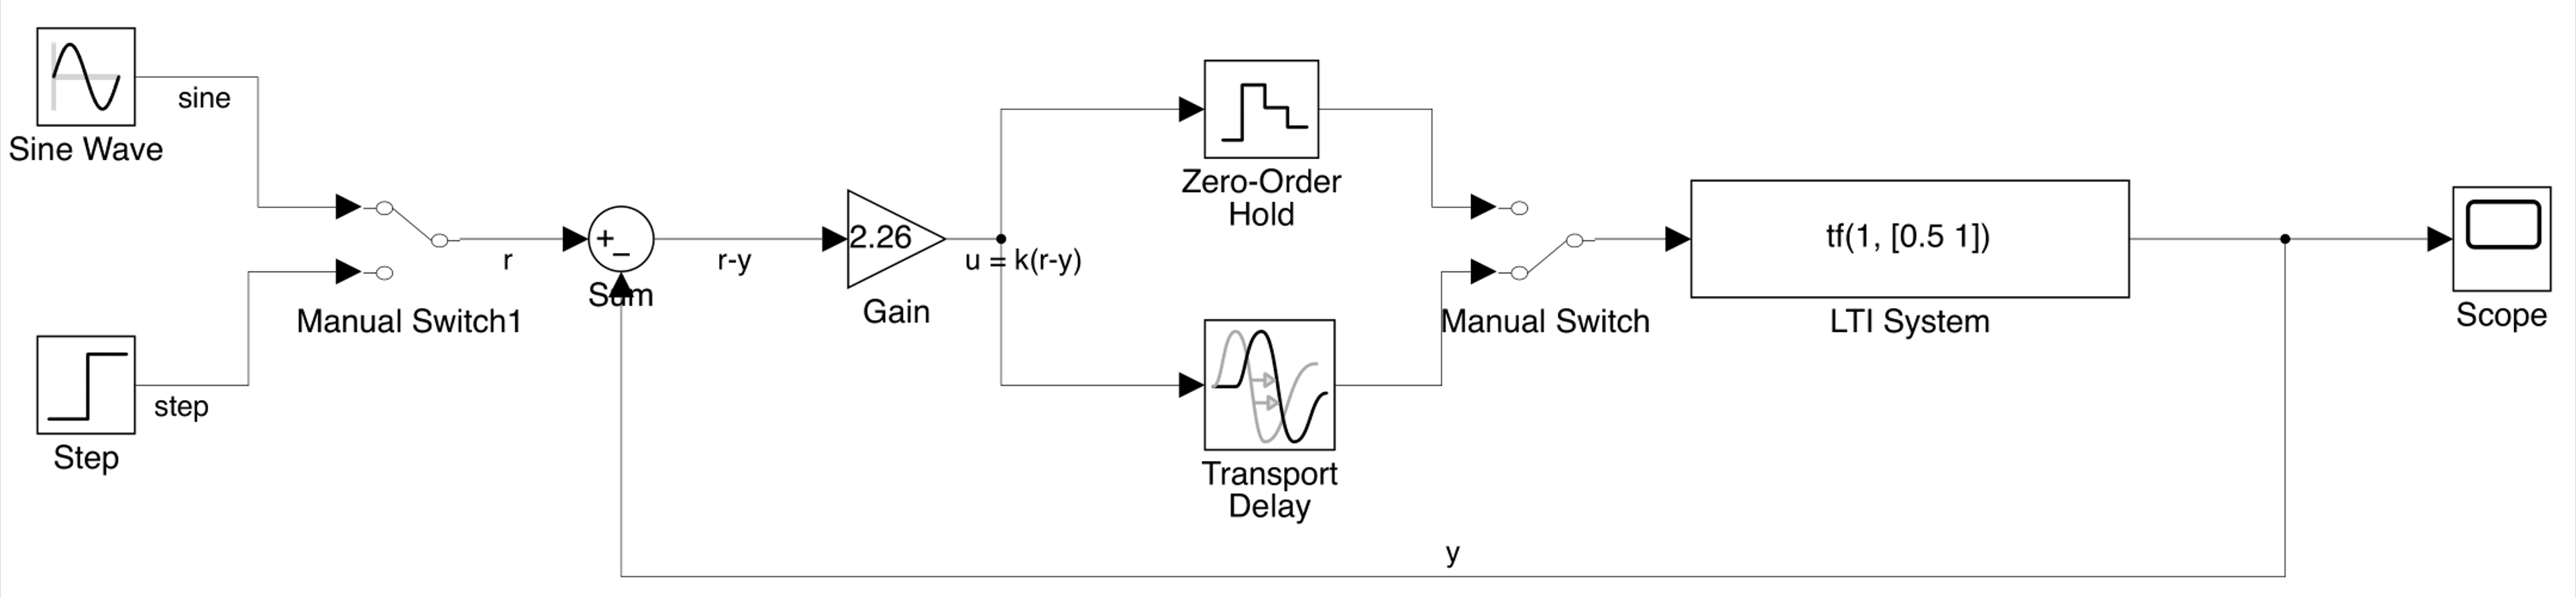

The value for $k$ was varied to determine close-loop instability for two inputs: a step response $1\left(t\right)$ and a sine wave.

First, let's look at the step response $1\left(t\right)$:

$k=-1\ldotp 1$ – **Unbounded**

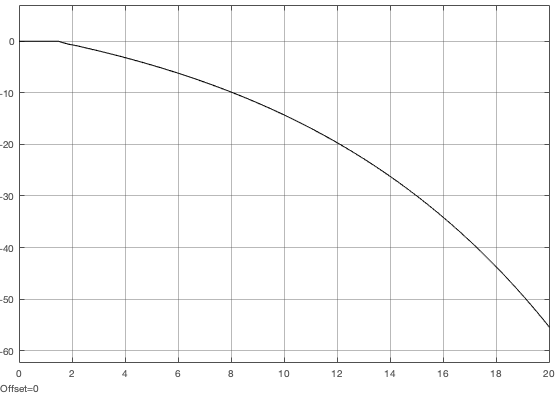

$k=-0\ldotp 9$ – **Bounded**

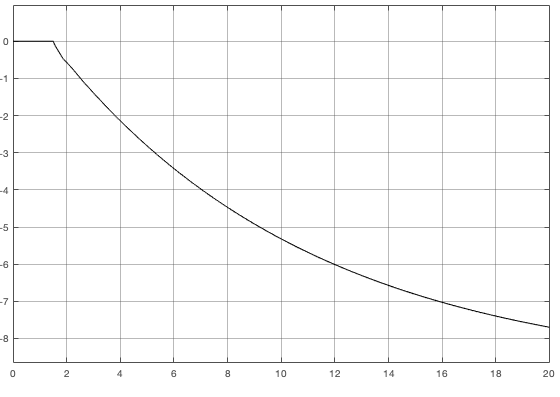

$k=-0\ldotp 1$– **Bounded**

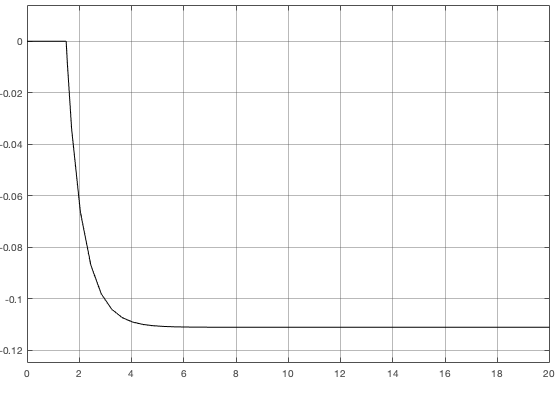

$k=1$ – **Bounded**

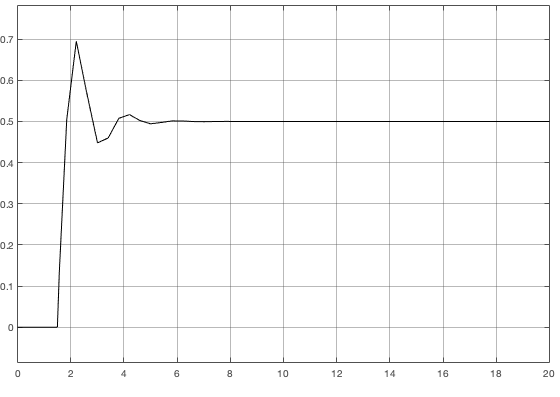

$k=2\ldotp 26$ – **Bounded**

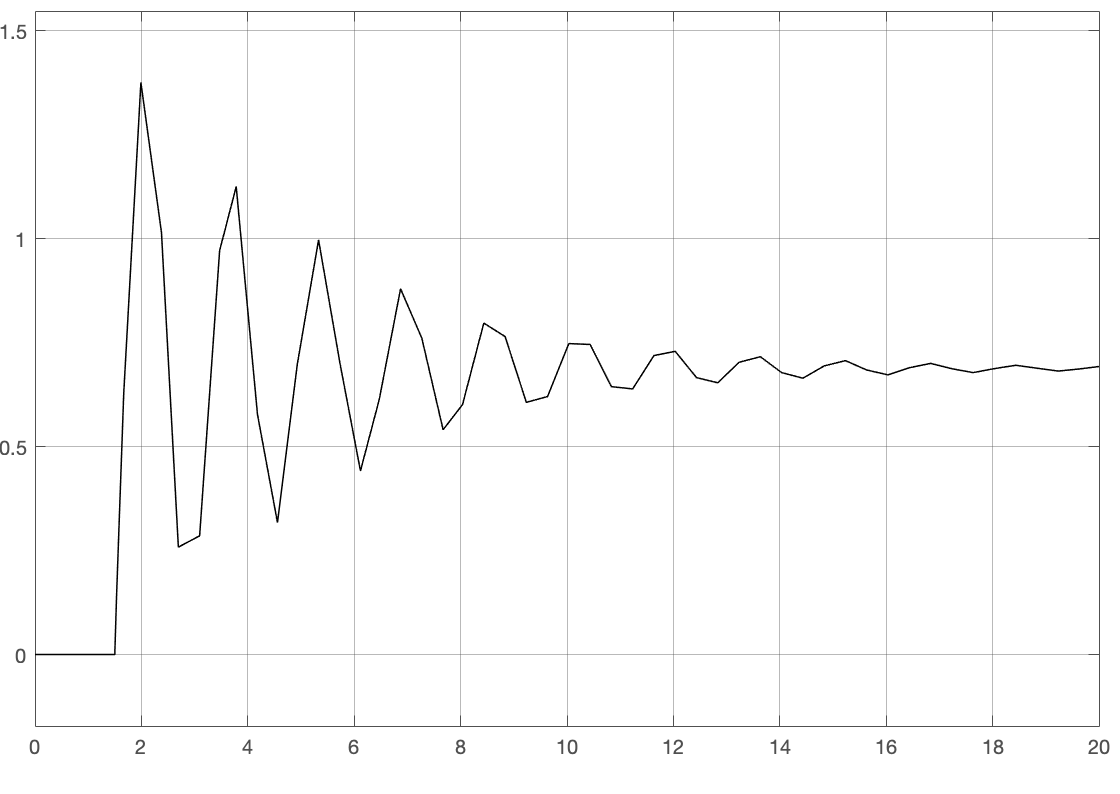

$k=2\ldotp 6$ – **Bounded**

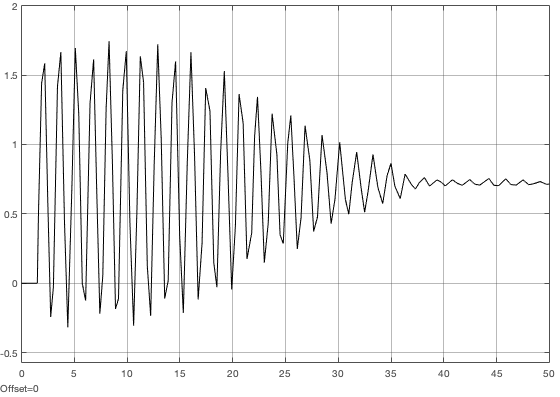

$k=2\ldotp 75$ – **Unbounded**

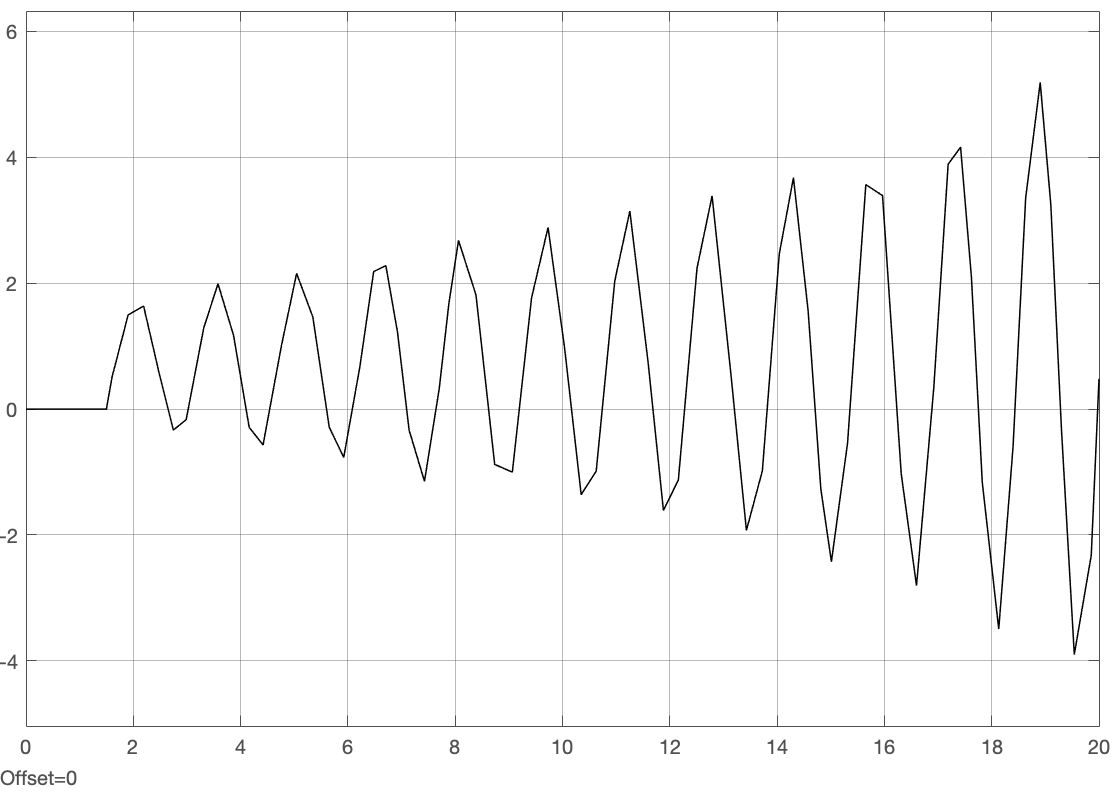

**Range of **$k$** that leads to stability : **$-1<k<2\ldotp 75$

Observation: While the Nyquist plot pointed towards an upper bound of $k\;$to be around 2.27, upper bound for the simulated system is around 2.7, after which the system leads to unbounded results. 

When the input is a sine function:

$k=-1\ldotp 1$ – **Unbounded**

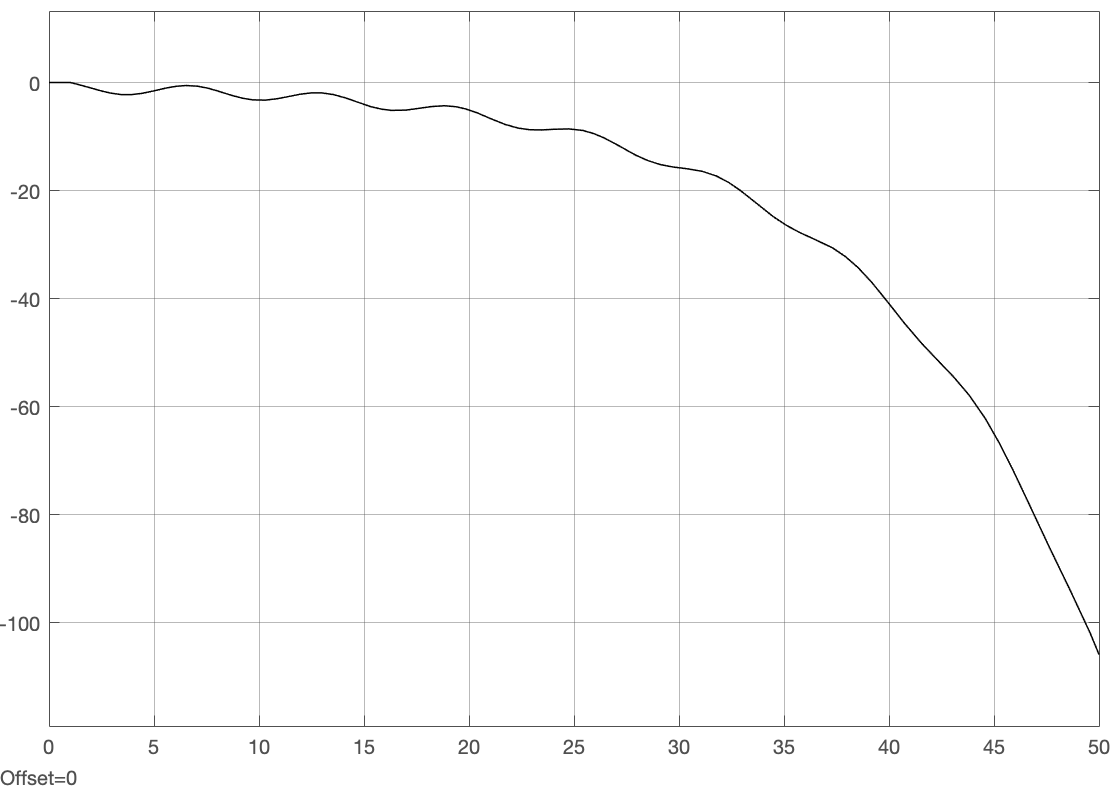

$k=-0\ldotp 9$ – **Bounded**

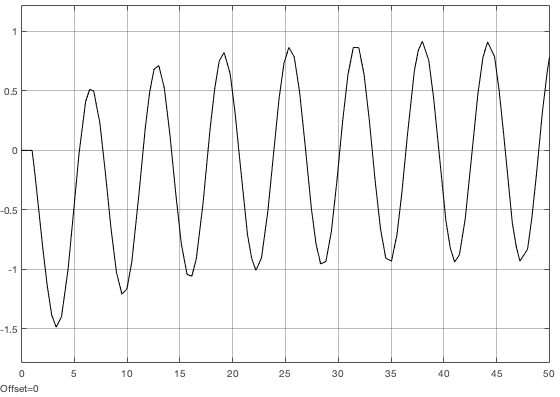

$k=1$ – **Bounded**

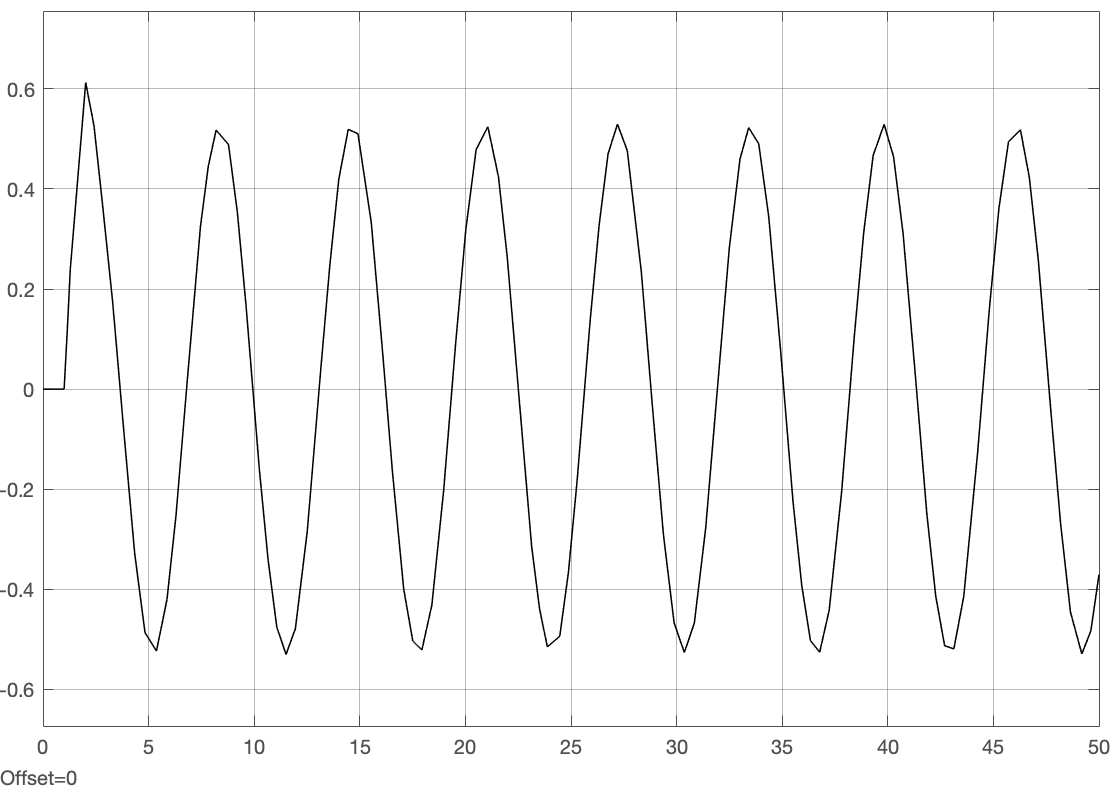

$k=2\ldotp 2$ – **Bounded**

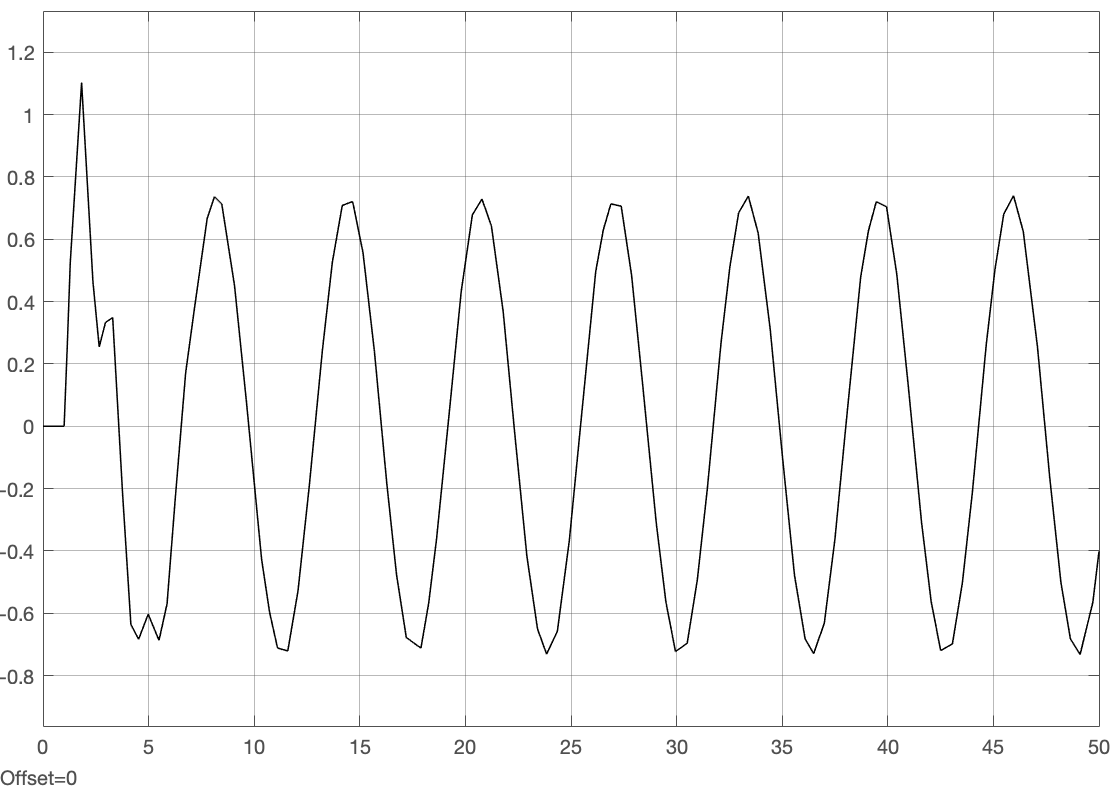

$k=2\ldotp 6$ – **Bounded**

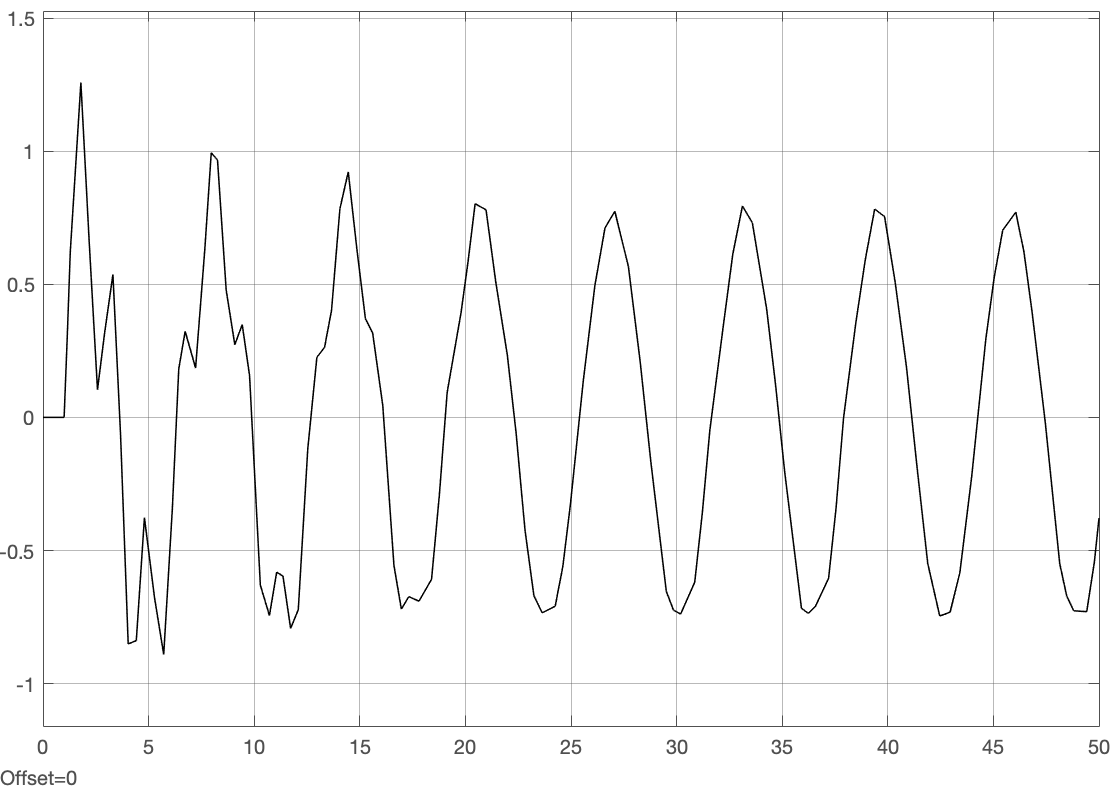

$k=2\ldotp 75$ – **Unbounded**

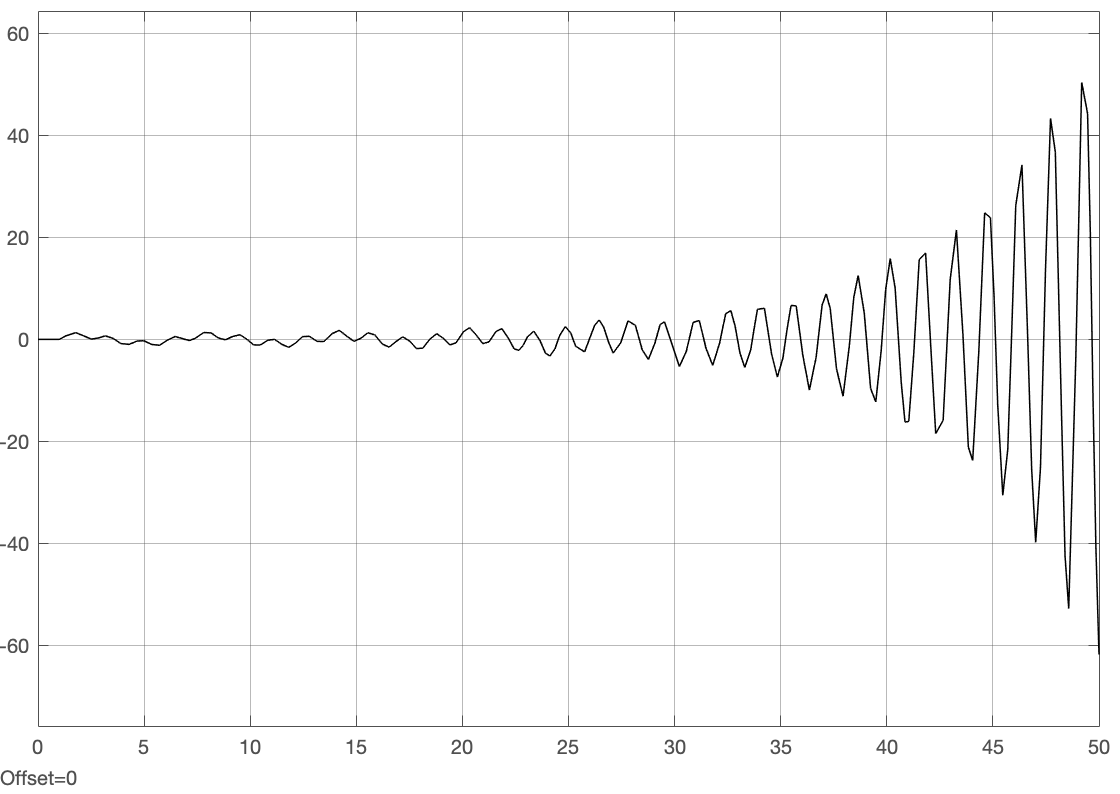

**Range of **$k$** that leads to stability : **$-1<k<2\ldotp 75$

Observation: While the Nyquist plot pointed towards an upper bound of $k\;$to be around 2.27, upper bound for the simulated system is around 2.7, after which the system leads to unbounded results. 

Similarly, varying the frequency of the sine wave and determining the respective values of $k$ that lead to stability

$f=0\ldotp 5$ => $-1<k<2\ldotp 75$

$f=1\ldotp 0$ => $-1<k<2\ldotp 75$

$f=2\ldotp 0$ =>  $-1<k<2\ldotp 75$

$f=10\ldotp$ =>  $-1<k<2\ldotp 4$

$f=20\ldotp$ =>  $-1<k<2\ldotp 26$

An interesting obersvation is that when $f$increases, the upper bound for $k$ tends towards the value obtained from the Nyquist plot. 

**(iii) Replace Transport Delay with Zero-Order Delay**

For the step function, with $k=1\ldotp 30$ – **Bounded**

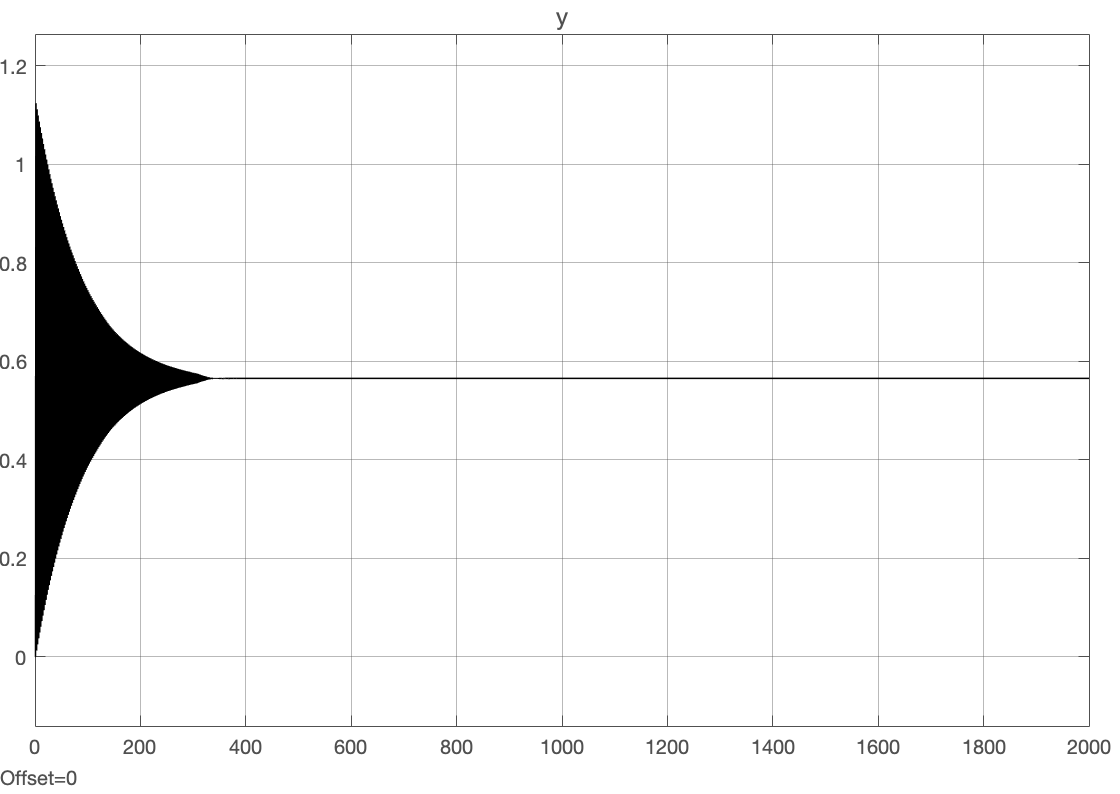

For the step funtion, with $k=1\ldotp 375$ – **Unbounded**

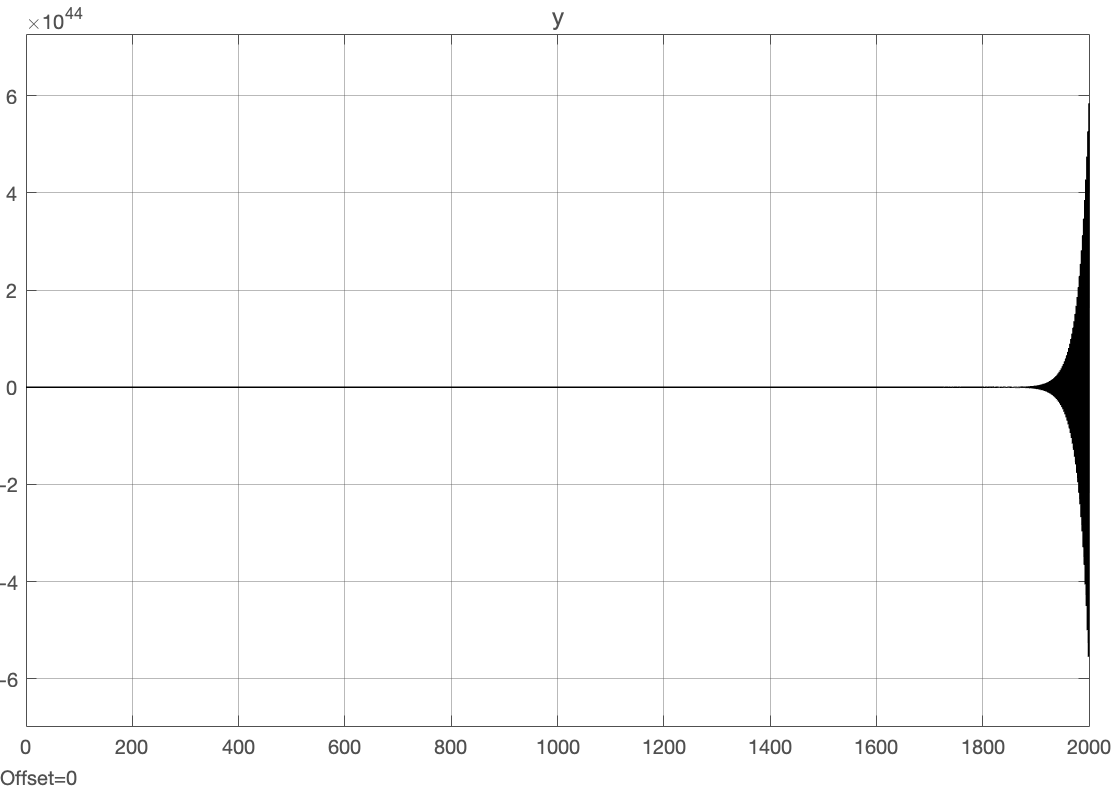

The lower bound is not affected by the zero-order hold. When a sine wave is used as an input, the same bounds are obtained. Hence, for a zero-order hold, **values of **$k$** that lead to a bounded output are: **$-1<k<1\ldotp 375$

**(iv) Discretize Continuous Plant **$G_0 \left(s\right)$**and apply feedback control **$u=k\left(r-y\right)$

G0 = tf(1, [0.5 1]);
G0_d = c2d(G0, Ts)

G0_d =
 
    0.8647
  ----------
  z - 0.1353
 
Sample time: 1 seconds
Discrete-time transfer function.



Using $G_{0,d} \left(z\right)$in the same Simulink model as 3.2.2 (ii-iii), $k$ was varied to determine if the previous range of $k$leads to stability for the discretized plant too. Note that are is no need for a zero-order hold or transform delay block.

$\mathit{\mathbf{r}}=1\left(\mathit{\mathbf{t}}\right)$:

$k=-1\ldotp 1$ – **Unbounded**

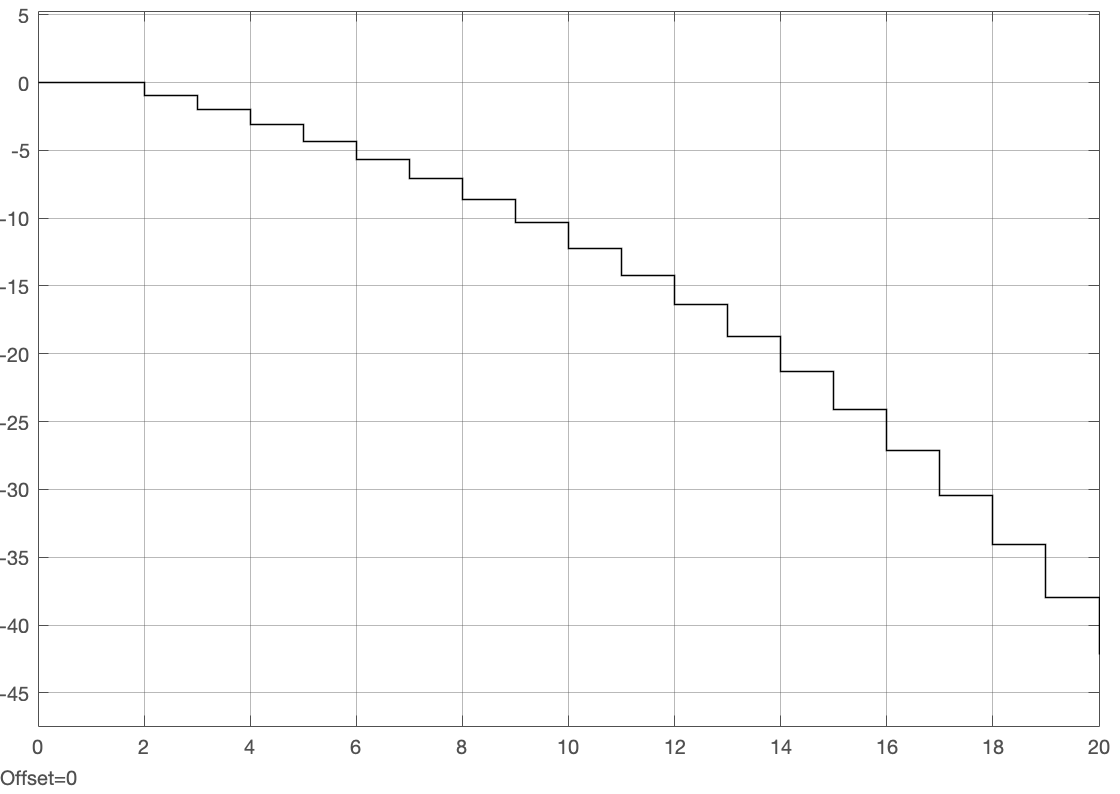

$k=-0\ldotp 9$ – **Bounded**

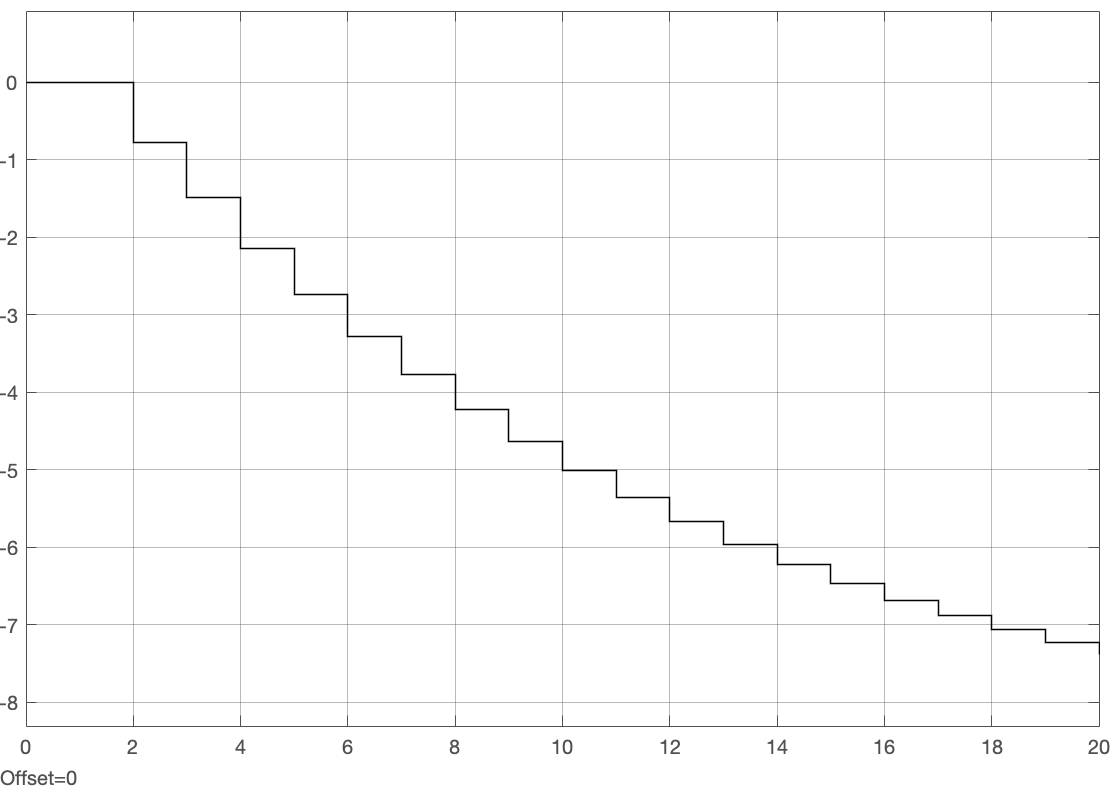

$k=-0\ldotp 1$ – **Bounded**

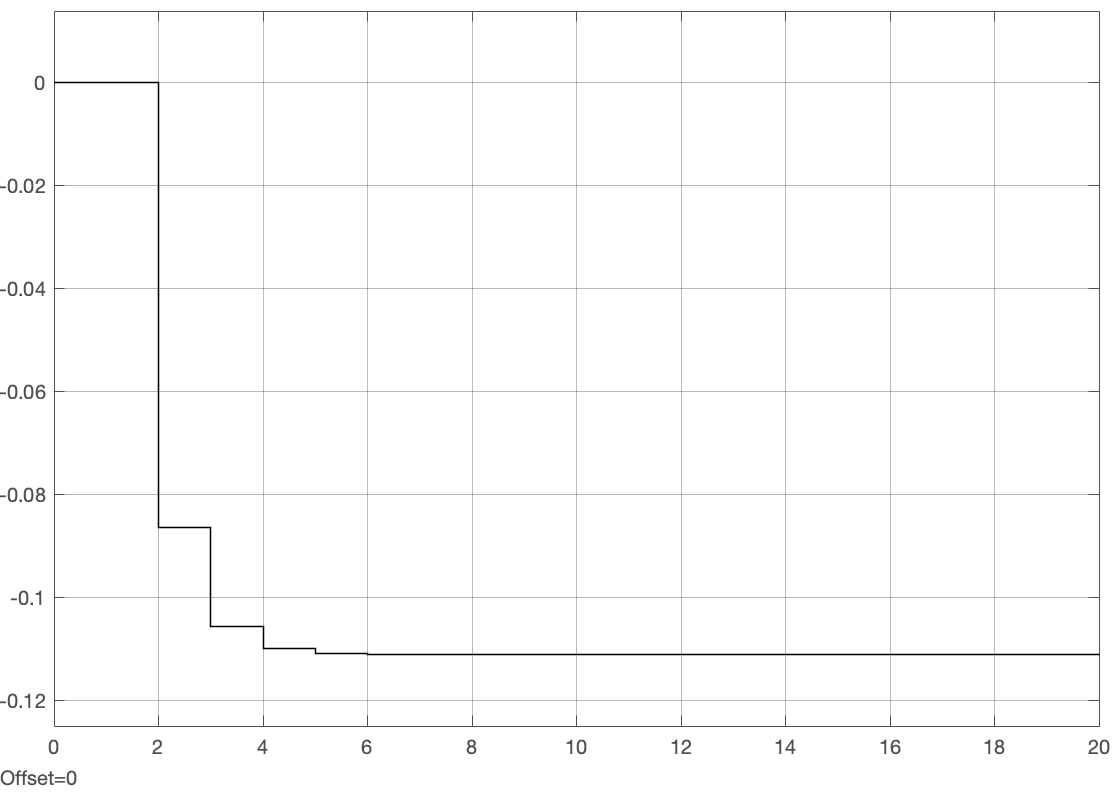

$k=1$ – **Bounded**

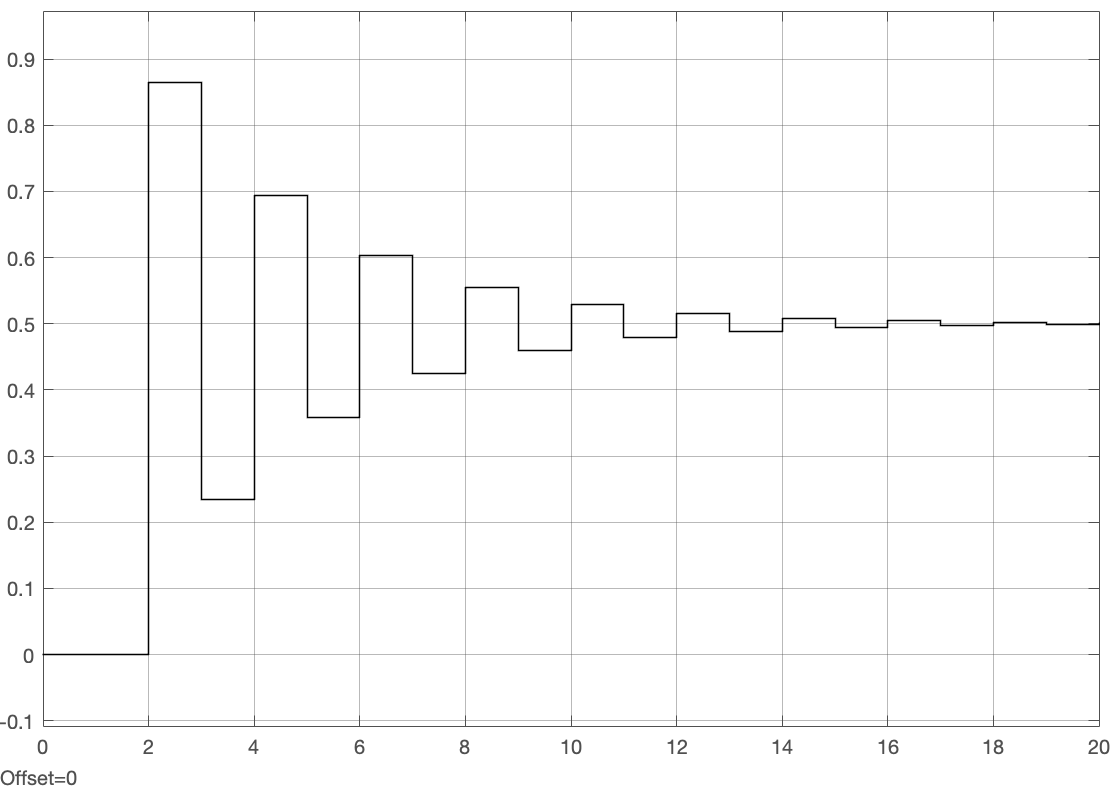

$k=1\ldotp 3$ – **Bounded**

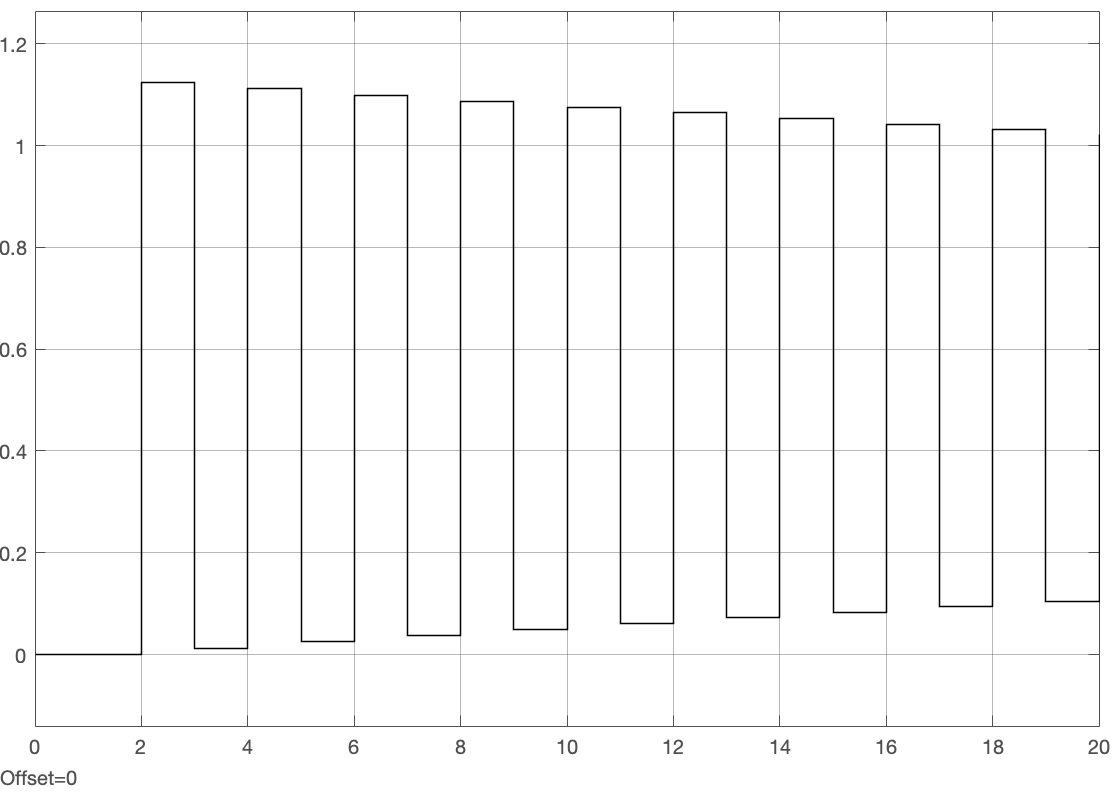

$k=1\ldotp 375$ – **Bounded**

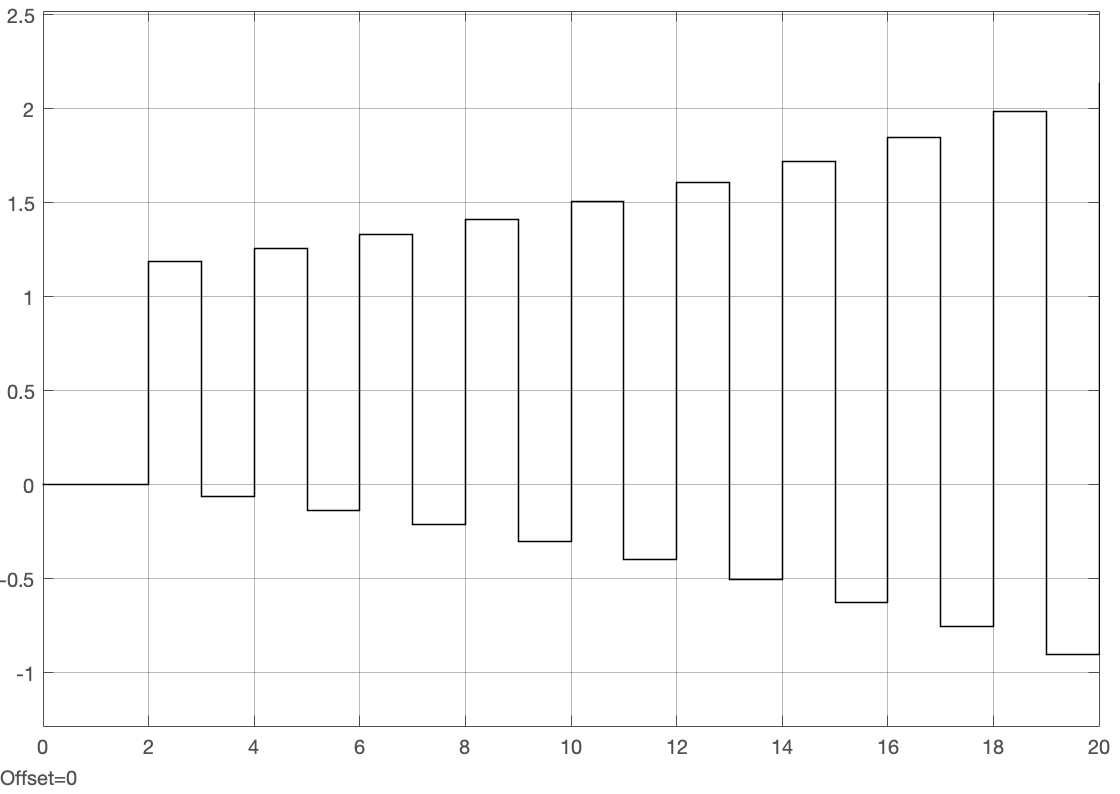

Hence, for a discretized plant, **values of **$k$** that lead to a bounded output are: **$-1<k<1\ldotp 375$ and are similar to that obtained from a zero-order hold

## 3. Inter-sample Ripple

We now consider a CT LTI plant $P(s) = \frac{0.1}{s(s+0.1)}$ and DT controller $C_d(z) = 9\frac{z-0.8}{z+0.8}$ with a system input-output sampling time of $T_s = 1 \text{ second}$.

Ps   = tf(0.1, [1 0.1 0]);
Pd_z = c2d(Ps, Ts);
Cd_z = 9*tf([1 -0.8], [1 0.8], Ts);

We now show below the step response of the DT closed-loop system (CLS) as well as the CT CLS, which has zero-order hold blocks at the input and output of the DT controller to interface with the CT plant.

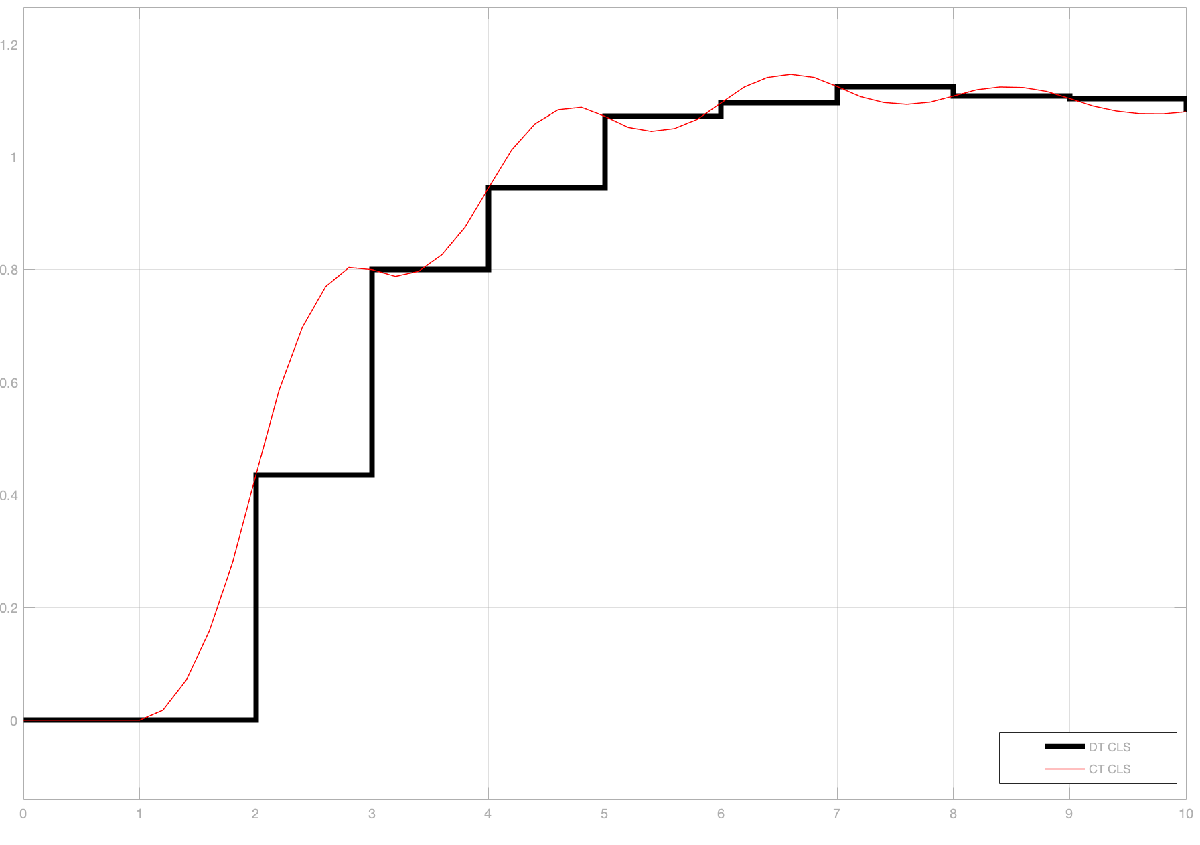

Here we have verified that the behvior of the CT CLS only matches that of the DT CLS at the discrete timesteps, which was a modelling assumption and constraint as noted in section 1. But the DT response serves as a good approximation especially with a well-designed controller (as in this case), since when the step-response is starting to converge, the inter-sample deviations also reduce and hence the DT system response matches more and more closely with the true CT behavior of the plant, as can be seen above.